## System Identification: Step Response

In this script, we wanted to reconstruct the step response of the single pendulum.

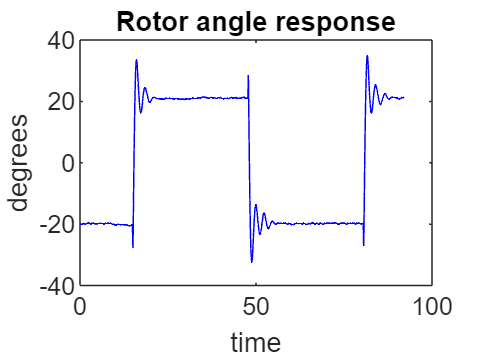

clear
close all
load("Edukit_Step Response Rotor Angle (degrees)__04-04-2023_11-16.mat");

%Creating time vector
t = 0: Sample_Period: Sample_Period*(length(rotor_command)-1);

plot(t, rotor_angle, 'b')
title("Rotor angle response")
xlabel("time");
ylabel("degrees");

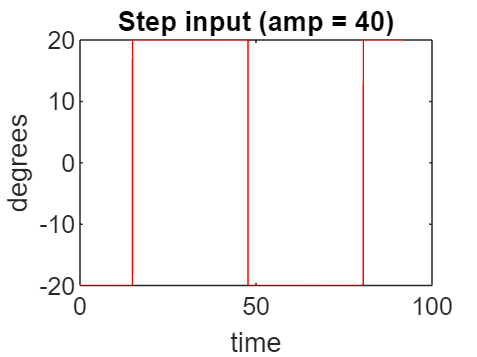


plot(t,rotor_command, 'r')
title("Step input (amp = 40)");
xlabel("time");
ylabel("degrees");

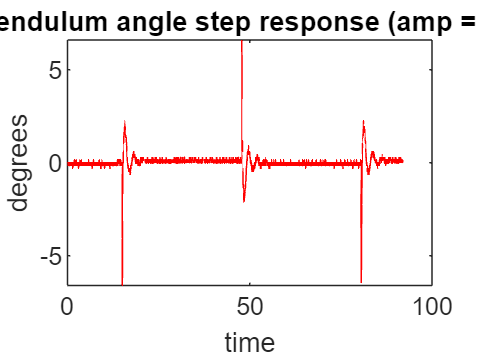


plot(t,pendulum_angle, 'r')
title("Pendulum angle step response");
xlabel("time");
ylabel("degrees");

%This is even easier than the step one since we can directly pass the rotor
%command (that is a perfect step) to the system identification and we don't
%have to replicate the input with our fingers (like we did for the impulse)

%the correct pendulum has 4 poles (-7.61,7.34 (for the PIP), 0,0 and 2
%zeros in 0.) Initially it doesn't respect the PIP because it doesn't have
%some couples of poles (RE>0) between 2 zeroes in the right semiplane so
%the system cannot be stabilized with a stable controller and since it is a
%digital controller, robustness against quantization and sampling errore
%must be ensured, so a stable controller is needed (system strongly stab)
%so ST added a pole with RE>0 with an inner loop realized via PD controller

%può essere che diventa robusto anche contro incertezze? anche perché un
%compensatore che deve dare ingressi sempre più grandi (per compensare che
%si esce da linear zone) dà problemi se ci sono errori numerici dovuti a
%sampling e quantization errors
